# SNW_VFI_UNEMP (Vectorized) Small Solution Analysis Unemployment

This is the example vignette for function: [**snw_vfi_unemp**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/svalpol/snw_vfi_unemp.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function using Exact Vectorized Solution. Small Solution Analysis. Unemployment Shock. The file focuses on the change in value function, asset choice, and consumption choice given a one period unemployment shock (that does not reappear in the future again).

## Test SNW_VFI_UNEMP Defaults Small

Solve the Regular Value and Also the Unemployment Value.

First, solve for value without unemployment issue (use the vectorized code that was previously tested):

mp_params = snw_mp_param('default_small');
mp_controls = snw_mp_control('default_test');
[V_VFI_ss,ap_VFI_ss,cons_VFI_ss,exitflag_VFI_ss] = ...
    snw_vfi_main_bisec_vec(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:18 of 18
SNW_VFI_MAIN: Finished Age Group:17 of 18
SNW_VFI_MAIN: Finished Age Group:16 of 18
SNW_VFI_MAIN: Finished Age Group:15 of 18
SNW_VFI_MAIN: Finished Age Group:14 of 18
SNW_VFI_MAIN: Finished Age Group:13 of 18
SNW_VFI_MAIN: Finished Age Group:12 of 18
SNW_VFI_MAIN: Finished Age Group:11 of 18
SNW_VFI_MAIN: Finished Age Group:10 of 18
SNW_VFI_MAIN: Finished Age Group:9 of 18
SNW_VFI_MAIN: Finished Age Group:8 of 18
SNW_VFI_MAIN: Finished Age Group:7 of 18
SNW_VFI_MAIN: Finished Age Group:6 of 18
SNW_VFI_MAIN: Finished Age Group:5 of 18
SNW_VFI_MAIN: Finished Age Group:4 of 18
SNW_VFI_MAIN: Finished Age Group:3 of 18
SNW_VFI_MAIN: Finished Age Group:2 of 18
SNW_VFI_MAIN: Finished Age Group:1 of 18
Elapsed time is 1.157178 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test


Second, solve for the unemployment value, use the exact-bisec result code, call the snw_vfi_main_bisec_vec.m function with a third input of existing value:

mp_params('xi') = 0.5;
mp_params('b') = 0;
[V_VFI_unemp,ap_VFI_unemp,cons_VFI_unemp,exitflag_VFI_unemp] = ...
    snw_vfi_main_bisec_vec(mp_params, mp_controls, V_VFI_ss);

SNW_VFI_MAIN: Finished Age Group:1 of 18
SNW_VFI_MAIN: Finished Age Group:2 of 18
SNW_VFI_MAIN: Finished Age Group:3 of 18
SNW_VFI_MAIN: Finished Age Group:4 of 18
SNW_VFI_MAIN: Finished Age Group:5 of 18
SNW_VFI_MAIN: Finished Age Group:6 of 18
SNW_VFI_MAIN: Finished Age Group:7 of 18
SNW_VFI_MAIN: Finished Age Group:8 of 18
SNW_VFI_MAIN: Finished Age Group:9 of 18
SNW_VFI_MAIN: Finished Age Group:10 of 18
SNW_VFI_MAIN: Finished Age Group:11 of 18
SNW_VFI_MAIN: Finished Age Group:12 of 18
SNW_VFI_MAIN: Finished Age Group:13 of 18
SNW_VFI_MAIN: Finished Age Group:14 of 18
SNW_VFI_MAIN: Finished Age Group:15 of 18
SNW_VFI_MAIN: Finished Age Group:16 of 18
SNW_VFI_MAIN: Finished Age Group:17 of 18
SNW_VFI_MAIN: Finished Age Group:18 of 18
Elapsed time is 1.004326 seconds.
Completed SNW_VFI_MAIN 1 PERIOD UNEMP SHK;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test


## Difference Between Value and Choices In Unemployment and Future Periods

V_VFI_unemp_drop = V_VFI_ss - V_VFI_unemp;
ap_VFI_unemp_drop = ap_VFI_ss - ap_VFI_unemp;
cons_VFI_unemp_drop = cons_VFI_ss - cons_VFI_unemp;

## Small Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 22:5:97, 100];
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log

#### MEAN(VAL(A,Z) - VAL(A,Z|unemp)), MEAN(AP(A,Z) - AP(A,Z|unemp)), MEAN(C(A,Z) - C(A,Z|unemp))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(v(A,Z) - v(A,Z|unemp))", V_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(v(A,Z) - v(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5
    _____    ________    __________    __________    __________    __________    __________

      1             0        1.6904        1.2304       0.92215       0.71052       0.55573
      2      0.013744        1.5058        1.1446       0.88221       0.69215       0.54755
      3       0.10995       0.84929       0.77131       0.68526       0.58977       0.49905
      4       0.37109       0.48942       0.50198       0.47875       0.45598       0.41598
      5       0.87963       0.31321       0.34983        0.3639       0.35226       0.34011
      6         1.718       0.19402       0.22847      

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z) - AP(A,Z|unemp))", ap_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z) - AP(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5
    _____    ________    __________    __________    __________    __________    __________

      1             0    0.0022484      0.014867      0.057905      0.15647       0.34681  
      2      0.013744     0.003487      0.017649      0.063115       0.1618       0.35273  
      3       0.10995     0.027386      0.051108        0.1055      0.20543       0.39161  
      4       0.37109     0.090127        0.1312       0.20257      0.31794       0.49125  
      5       0.87963      0.11935       0.17223       0.22317      0.35003       0.56122  
      6         1.718      0.11986       0.18199     

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z) - C(A,Z|unemp))", cons_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z) - C(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1     mean_eta_2     mean_eta_3    mean_eta_4    mean_eta_5
    _____    ________    ___________    ___________    __________    __________    __________

      1             0          0.122        0.17481       0.23386      0.29567       0.35846 
      2      0.013744         0.1207        0.17197       0.22861       0.2903       0.35252 
      3       0.10995       0.096421        0.13816       0.18593      0.24645       0.31349 
      4       0.37109       0.032761       0.057208      0.088128      0.13338       0.21345 
      5       0.87963      0.0021476       0.014803      0.066317      0.10032       0.14279 
      6         1.718     5.7421e-05     

Graph Mean Values Change:

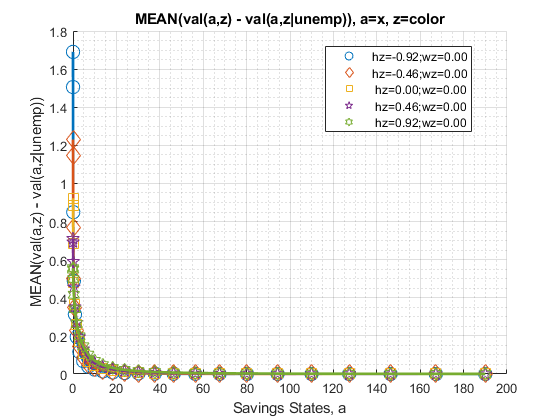

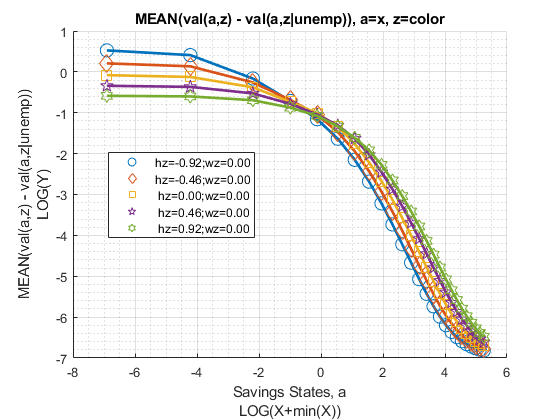

mp_support_graph('cl_st_graph_title') = {'MEAN(val(a,z) - val(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(val(a,z) - val(a,z|unemp))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices Change:

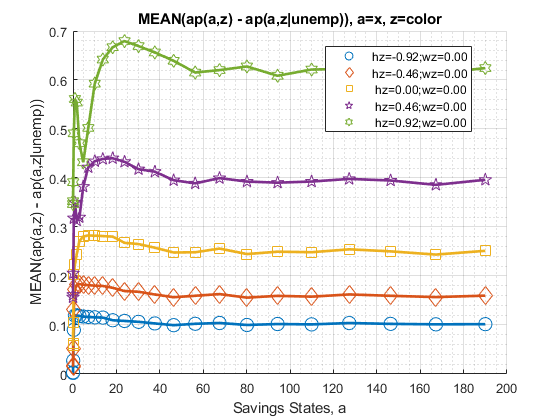

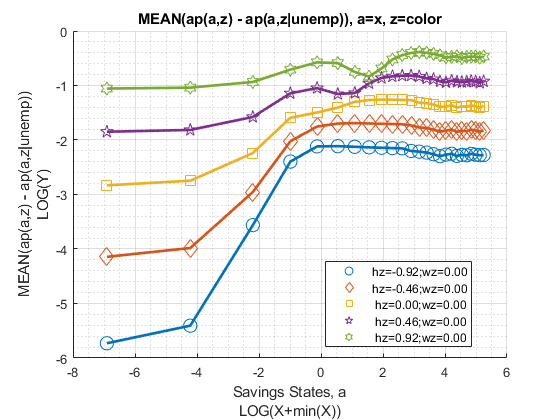

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(a,z) - ap(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(a,z) - ap(a,z|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption Change:

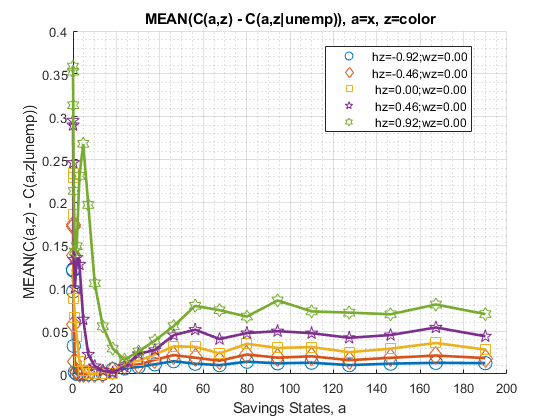

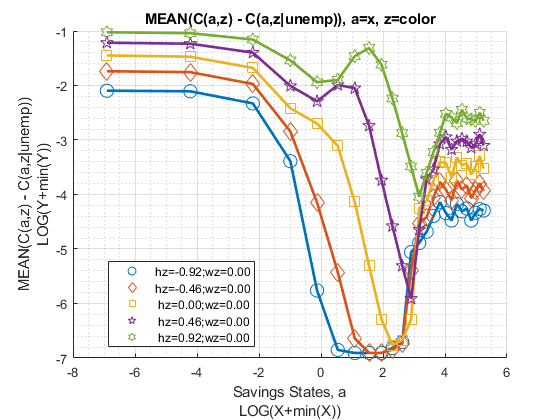

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z) - C(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z) - C(a,z|unemp))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(V(KM,J) - V(KM,J | unemp)), MEAN(ap(KM,J) - ap(KM,J | unemp)), MEAN(c(KM,J) - c(KM,J | unemp))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(V(KM,J) - V(KM,J | unemp))", V_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(V(KM,J) - V(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(ap(KM,J) - ap(KM,J | unemp))", ap_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(ap(KM,J) - ap(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(c(KM,J) - c(KM,J | unemp))", cons_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(c(KM,J) - c(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    

Graph Mean Values Change:

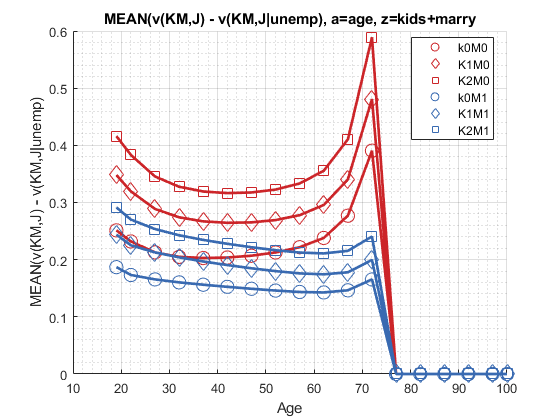

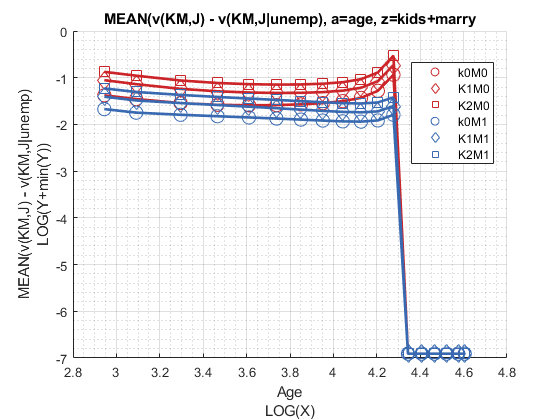

mp_support_graph('cl_st_graph_title') = {'MEAN(v(KM,J) - v(KM,J|unemp), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(v(KM,J) - v(KM,J|unemp)'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices Change:

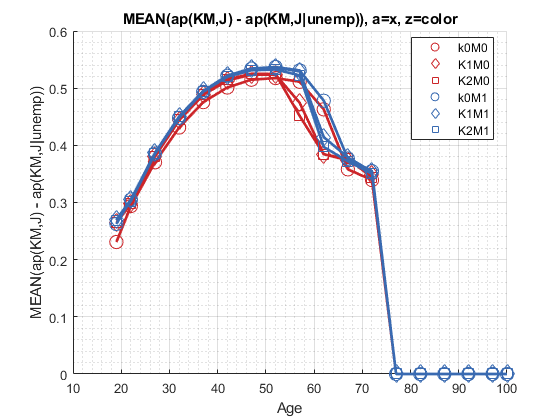

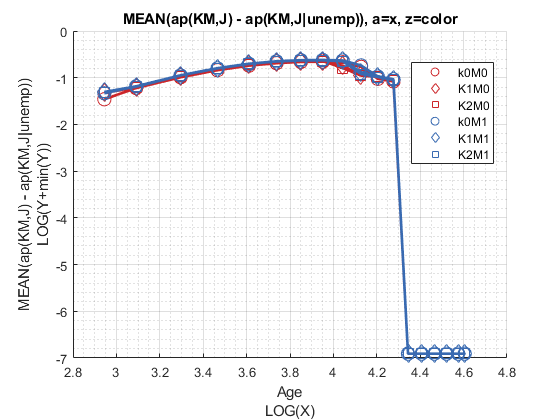

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(KM,J) - ap(KM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(KM,J) - ap(KM,J|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption Change:

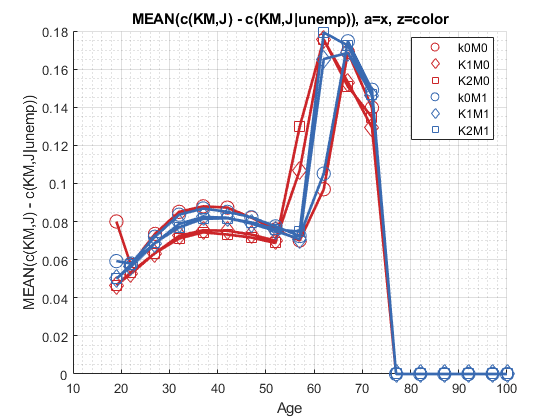

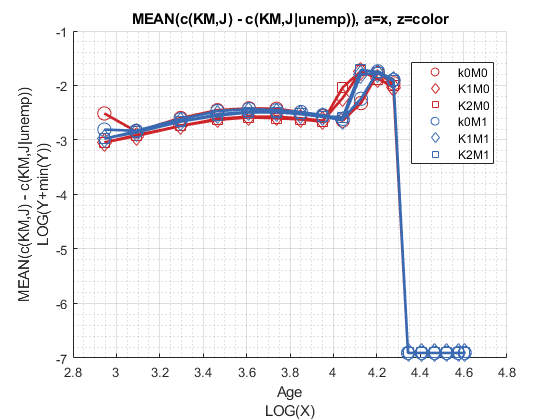

mp_support_graph('cl_st_graph_title') = {'MEAN(c(KM,J) - c(KM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(c(KM,J) - c(KM,J|unemp))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(v(EKM,J) - v(EKM,J|unemp)), MEAN(ap(EM,J) - ap(EM,J|unemp)), MEAN(c(EM,J) - c(EM,J|unemp))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(v(EM,J) - v(EM,J|unemp))", V_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(v(EM,J) - v(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    __

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(ap(EM,J) - ap(EM,J|unemp))", ap_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(ap(EM,J) - ap(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(c(EM,J) - c(EM,J|unemp))", cons_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(c(EM,J) - c(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    __

Graph Mean Values Change:

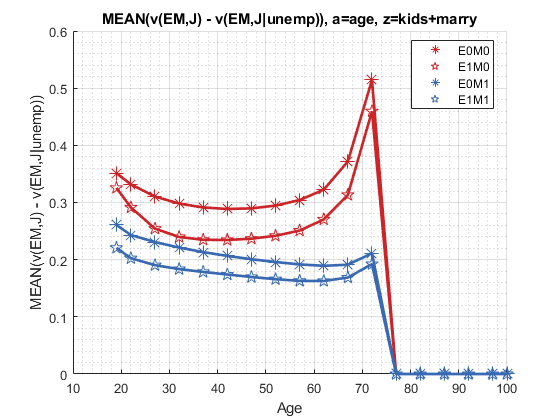

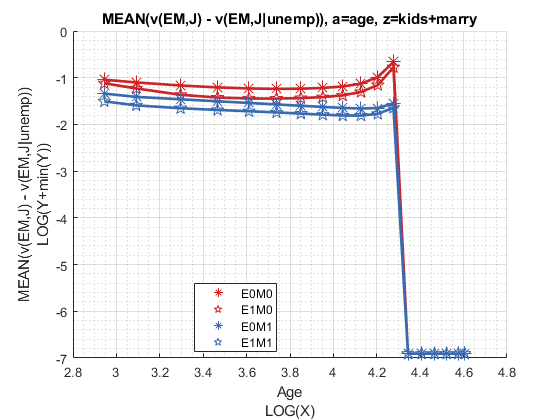

mp_support_graph('cl_st_graph_title') = {'MEAN(v(EM,J) - v(EM,J|unemp)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(v(EM,J) - v(EM,J|unemp))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices Change:

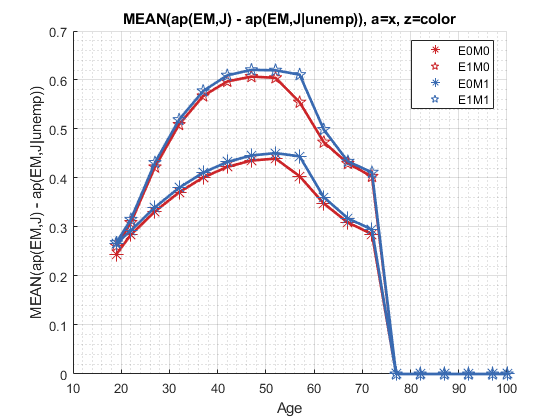

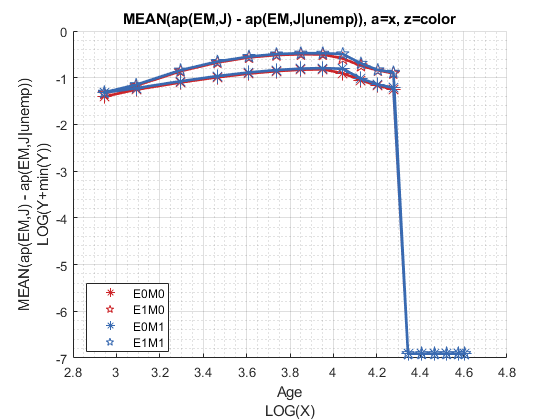

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(EM,J) - ap(EM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(EM,J) - ap(EM,J|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption Change:

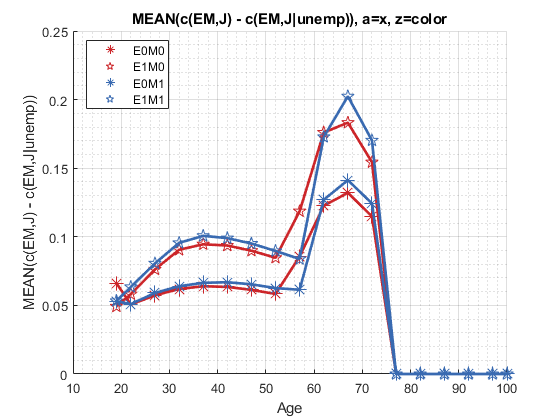

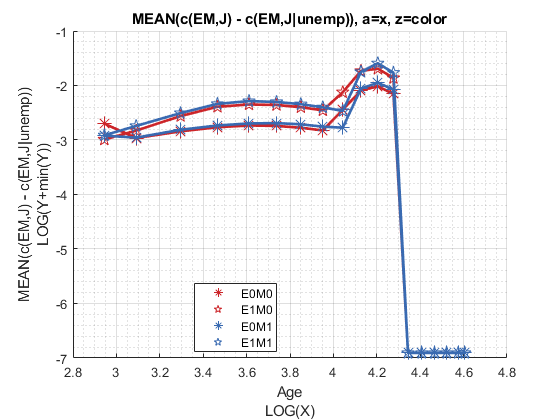

mp_support_graph('cl_st_graph_title') = {'MEAN(c(EM,J) - c(EM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(c(EM,J) - c(EM,J|unemp))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);